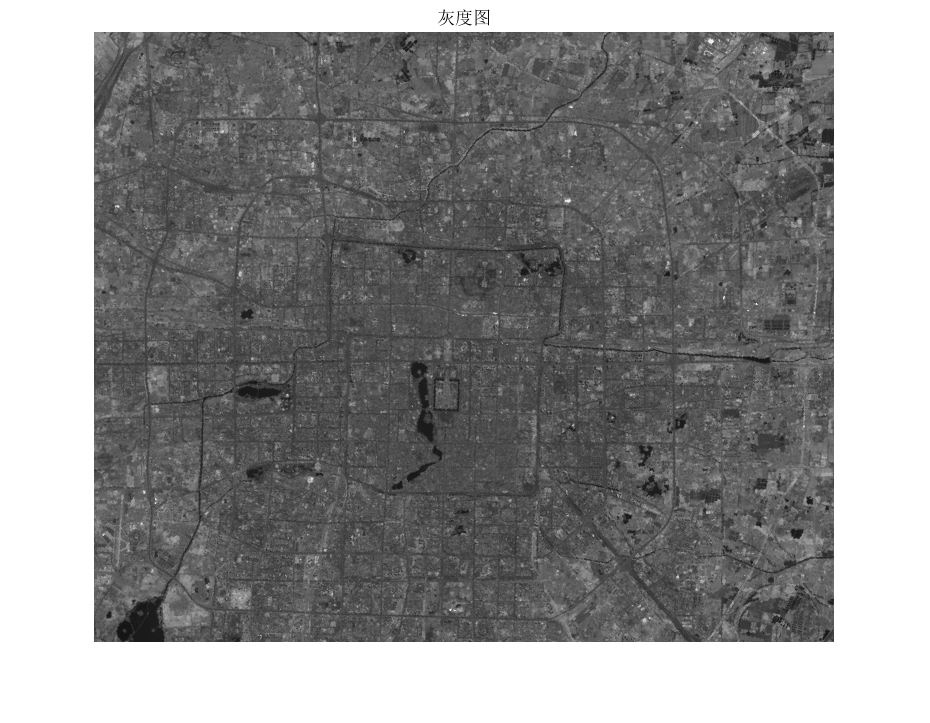

clear all;
clc;

% 导入图像
IMG=im2double(imread('D:\2022大二下学期\模式识别课间实习\2020302131195 廖非凡 遥感\input\beijing.tif'))*255;
row = length(IMG(:,1,:));   %图像排数
col = length(IMG(1,:,:));   %图像列数
bds = size(IMG,3);   %图像波段数

% 参数
nHid1 = 8;
nHid2 = 10;
nEpoch = 500;
nBatch = 32;
lr = 1e-3;
m = 0.9;

% 显示灰度图像
gray = mean(IMG,3)/255;

figure;
imshow(gray);
title('灰度图');

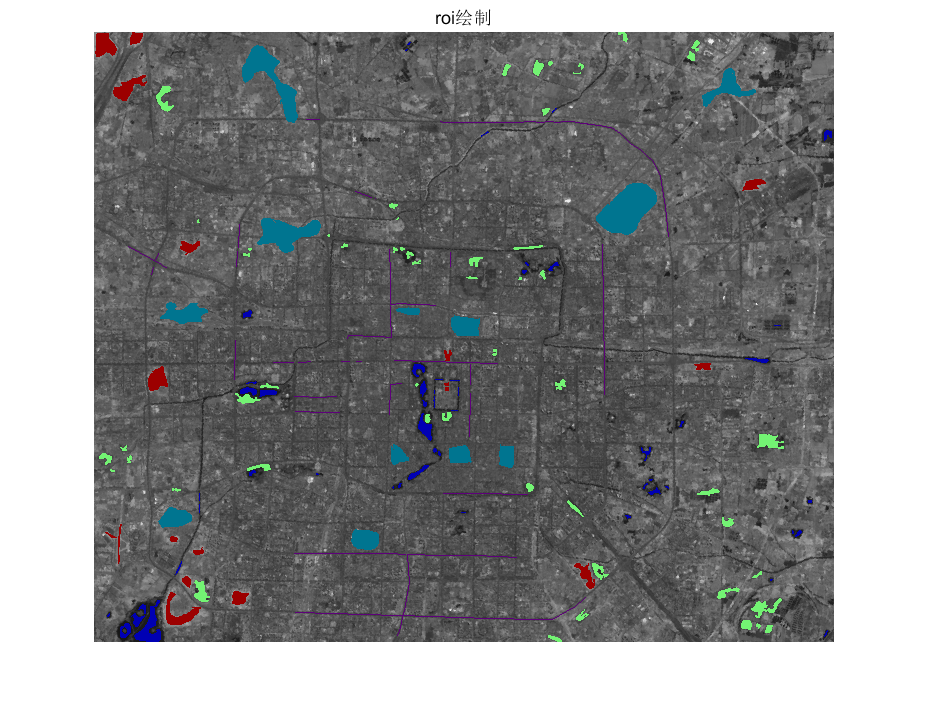


% 导入训练集
[class_data,nClass,names] = input_data('D:\2022大二下学期\模式识别课间实习\2020302131195 廖非凡 遥感\roi_data\roi_data001.csv', bds);

% 绘制训练集
res_pic = cat(3,gray,gray,gray);

% 随机选择颜色
if nClass ~= 5
    colors = add_rand_color(nClass);
else
    colors =[0	0	0.70443;%water
        0.45 0.95474	0.45;%tree
        0.61181	0	0;%ground
        0	0.45706	0.56407;% city
        0.36753	0	0.4835];% road
end

for class = 1:nClass
    % 调取x，y数组
    X = class_data{class,1}{1,1};
    Y = class_data{class,1}{1,2};
    
    for i = 1:class_data{class,1}{1,4}
        x = X(i)+1;
        y = Y(i)+1;
        res_pic(y,x,1) = colors(class,1);
        res_pic(y,x,2) = colors(class,2);
        res_pic(y,x,3) = colors(class,3);
    end
end

figure;
imshow(res_pic);
title("roi绘制");

历时 27.605704 秒。


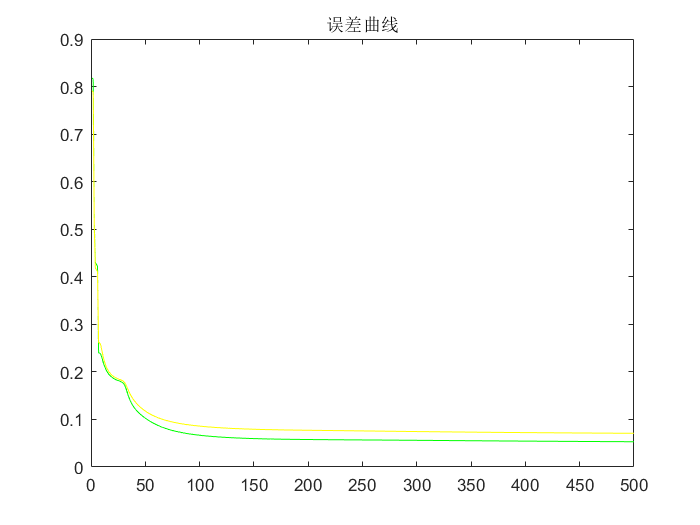

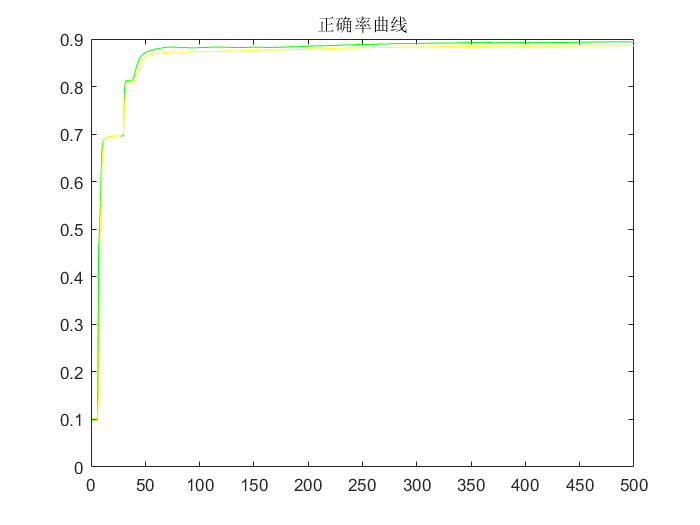


% 下面开始进行分类算法
% 加载参数
datas = rand_list2neural(class_data);

[w1,w2,w3] = train_neural_net(nClass, nHid1,nHid2, nEpoch, nBatch, lr, m, datas);


% 进行分类
tic;                                
bar = waitbar(0,'分类中...');  
for x = 1:row
    for y = 1:col
        % 计算类别
        data =reshape(IMG(x,y,:),1,bds);
        result = eval_neural_net(w1,w2,w3,data);
        
        % 染色
        res_pic(x,y,1) = colors(result,1);
        res_pic(x,y,2) = colors(result,2);
        res_pic(x,y,3) = colors(result,3);
        
    end
    % 显示进度
    str=['分类中...',num2str(100*x/row),'%'];
    waitbar(x/row,bar,str) 
end
close(bar);            
toc;

历时 10.823359 秒。


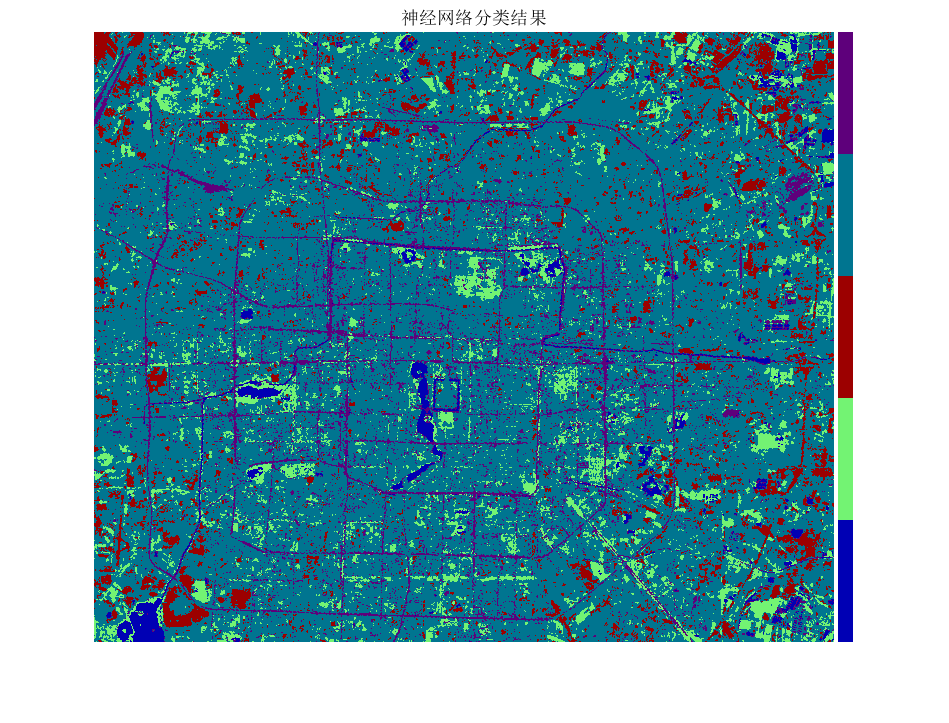


figure;
imshow(add_Color_bar(res_pic, colors));   
title('神经网络分类结果');


bar1 = waitbar(0,'计算混淆矩阵中...'); 
% 计算混淆矩阵
conf_matrix = zeros(nClass +1, nClass+1);
for class = 1:nClass
    for i = 1:class_data{class,1}{1,4}
        data = class_data{class,1}{1,3}(i,:);
        result = eval_neural_net(w1,w2,w3, data);
        
        % 更新混淆矩阵
        conf_matrix(class, result) = conf_matrix(class, result) + 1;
    end
    str1=['计算混淆矩阵中...',num2str(100*class/nClass),'%'];
    waitbar(x/row,bar1,str1);
end
close(bar1);

for class = 1:nClass
    conf_matrix(nClass+1, class) = sum(conf_matrix(:, class));
    conf_matrix(class, nClass+1) = sum(conf_matrix(class, :));
end
conf_matrix(nClass+1,nClass+1) = sum(conf_matrix(nClass+1, :));

% 计算精度
correct = diag(conf_matrix);
acc = sum(correct(1:end-1))/conf_matrix(end,end);

disp('混淆矩阵为：');

混淆矩阵为：


disp(conf_matrix);

        1966           1           0           6          30        2003
          25        3021           2         138          32        3218
           0           1        2180         580           0        2761
           1         125         484        7490         187        8287
           1          53           0         352        1421        1827
        1993        3201        2666        8566        1670       18096



disp(strcat('正确率：',num2str(acc*100),'%'));

正确率：88.8484%


function [w11, w22, w33] = train_neural_net(nClass, nHid1,nHid2, nEpoch, nBatch, lr, m, datas)
% 神经网络
    % 读取输入输出
    x = datas{1,1};
    y = datas{1,2};
    
    % 数据的归一化
    x1 = ((x-0)/(255-0)).*2 -1;
    nS = length(x1);
    
        
        nX = length(x1(1,:));
        w1 = rand(nHid1,nX) .* 2;
        w2 = rand(nHid2, nHid1) .* 2;
        w3 = rand(nClass, nHid2) .* 2;
        
        
        % 用于添加动量
        w1b = zeros(nHid1,nX);
        w2b = zeros(nHid2, nHid1);
        w3b = zeros(nClass, nHid2);

    %%%%%%%%%%%%%%%%%%%%%%%%%%%%训练%%%%%%%%%%%%%%%%%%%%%%%%%%%%
        % 7:3 划分训练和测试集(数据预处理已打乱)
        
        S_tran = round(nS*0.7);
        
        x_tran = x1(1:S_tran, :);
        y_tran = y(1:S_tran, :);
        x_test = x1(S_tran+1:end, :);
        y_test = y(S_tran+1:end, :);
        

        
        % 计算Bach数目
        times = floor(S_tran/nBatch);
        left = mod(S_tran, nBatch);
        
        % 用于记录
        tran_error = [];
        test_error = [];
        acc_list = [];
        tran_acc = 0;
        tran_acc_list = [];
        
        tic;                                
        bar = waitbar(0,'训练中...');
        for i = 1:nEpoch
            % 按Bach读取数据训练
            for t = 1:times
                % 生成数据
                start_ = (t-1)*nBatch + 1;
                end_ = t*nBatch;
                xb = x_tran(start_:end_,:);
                y_batch = y_tran(start_:end_,:);
                yb = zeros(nClass, nBatch);
                for b = 1:nBatch
                    yb(y_batch(b,1),b) = 1;
                end
                
                % 前向传播
                [v_1,y_1,v_2,y_2,v,output] = forward_neural(w1,w2,w3,xb);
                
                % 反向传播
                [w1,w2,w3,~, w1b, w2b, w3b] = backward_neural(w1,w2,w3,xb,yb,output,v_1,y_1,v_2,y_2,v,lr, m, w1b, w2b, w3b);              
                % 计算精度
                [~,y_pred] = max(output);
                tran_acc = tran_acc + sum(y_pred == y_batch','all');
            end
            % 最后1Bach
            if left ~= 0
                % 生成数据
                xb = x_tran(end-left+1:end,:);
                
                y_batch = y_tran(end-left+1:end,:);
                yb = zeros(nClass, left);
                for b = 1:left
                    yb(y_batch(b,1),b) = 1;
                end
                
                % 前向传播
                [v_1,y_1,v_2,y_2,v,output] = forward_neural(w1,w2,w3,xb);
                
                % 反向传播
                [w1,w2,w3,error, w1b, w2b, w3b] = backward_neural(w1,w2,w3,xb,yb,output,v_1,y_1,v_2,y_2,v,lr, m, w1b, w2b, w3b);
                
                % 记录损失
                tran_error = [tran_error,mean(abs(error),"all")];
                
                % 计算精度
                [~,y_pred] = max(output);
                tran_acc = tran_acc + sum(y_pred == y_batch','all');
            end
         %%%%%%%%%%%%%%%%%%%%%%%%%%%%测试%%%%%%%%%%%%%%%%%%%%%%%%%%%%
         
            % 进行测试
            % 生成数据
                xb = x_test;
                yb = zeros(nClass, nS-S_tran);
                for b = 1:nS-S_tran
                    yb(y_test(b,1),b) = 1;
                end
                
                % 前向传播
                [~,~,~,~,~,output] = forward_neural(w1,w2,w3,xb);
                
                % 记录损失
                error = yb - output;
                test_error = [test_error,mean(abs(error),"all")];
                
                % 计算精度
                [~,y_pred] = max(output);
                acc = sum(y_pred == y_test','all')/length(y_pred);
                acc_list = [acc_list, acc];
                
                tran_acc_list = [tran_acc_list, tran_acc/length(x_tran)];
                tran_acc = 0;
                
                % 显示进度
                str=['训练中...',num2str(100*i/nEpoch),'%',' 正确率：',num2str(acc*100),'%'];
                waitbar(i/nEpoch,bar,str);
        end
        close(bar);            
        toc;
        
        % 绘制变化折线图
        x_list = 1:nEpoch;
        figure;
        plot(x_list,tran_error,'g',x_list,test_error,'y');
        title('误差曲线');
        
        figure;
        plot(x_list,acc_list,'g',x_list,tran_acc_list,'y');
        title('正确率曲线');
        
        w11 =w1;
        w22 =w2;
        w33 =w3;
end

function y_pred = eval_neural_net(w1,w2,w3,x)
    % 数据的归一化
    xb = ((x-0)/(255-0)).*2 -1;
    
    % 前向传播
    [~,~,~,~,~,output] = forward_neural(w1,w2,w3,xb);
    [~,y_pred] = max(output);
    
end